% Emmanuelle

% Script to fit velocity change

load('DataToFit.mat');
load('Time.mat');

TStart = 1;                     % (in s)
TStartStim = 10;                % (in s)
TEndStim = 20;                  % (in s)
Tstop = 60;                     % (in s)
ThresholdLevel = 0.1;           % (between 0 and 1)
Smoothing = 7;                  % number of points used for smoothing data and detecting the max

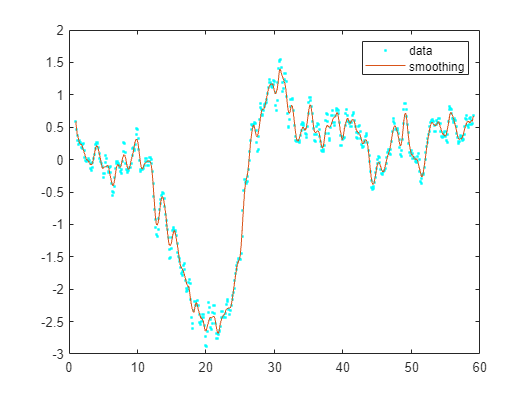

% average baseline
IdxBaseline = (Time >= TStart) & (Time <= TStartStim);
Baseline =  DataToFit(IdxBaseline);
VBaseline = mean(Baseline);

% max DataToFit
SmoothDataToFit = smooth(DataToFit,Smoothing);

% Plot smoothing with data.
figure( 'Name', 'smoothing' );
plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(Time, SmoothDataToFit)
legend( 'data', 'smoothing', 'Location', 'NorthEast', 'Interpreter', 'none' );
hold off


% Setup data to fit 
IndexFit = (Time >= TStart) & (Time <= Tstop);
[xData, yData] = prepareCurveData( Time(IndexFit), DataToFit(IndexFit));

% Set up fittype and options.
ft = fittype( 'a0/(1+(exp((x-x0)/T0)))+a1/(1+(exp(-(x-x1)/T1)))+a2/(1+(exp(-(x-x2)/T2)))^2+c', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 0 0 -Inf -Inf -Inf -Inf 10 10 10];
opts.StartPoint = [0.4 0.4 0.03 0.7 0.8 0.8 0.9 10 20 10];
opts.Upper = [Inf Inf Inf Inf Inf Inf Inf 60 60 Inf];


% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model:
     fitresult(x) = a0/(1+(exp((x-x0)/T0)))+a1/(1+(exp(-(x-x1)/T1)))+a2/(1+(exp(-
                    (x-x2)/T2)))^2+c
     Coefficients (with 95% confidence bounds):
       T0 =       3.001  (2.026, 3.975)
       T1 =       1.446  (0.9006, 1.991)
       T2 =       2.112  (1.26, 2.964)
       a0 =       4.563  (-2.968, 12.09)
       a1 =       7.228  (0.6296, 13.83)
       a2 =      -2.392  (-3.584, -1.199)
       c =      -4.531  (-12.07, 3.005)
       x0 =       26.59  (22.88, 30.3)
       x1 =       25.67  (25.32, 26.02)
       x2 =       13.27  (12.57, 13.96)

gof = struct with fields:
           sse: 39.2849
       rsquare: 0.9350
           dfe: 571
    adjrsquare: 0.9340
          rmse: 0.2623


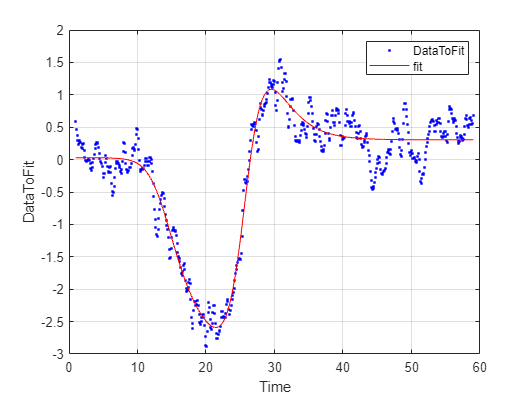

fitcoeffvals= coeffvalues(fitresult);

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, Time, DataToFit );
legend( h, 'DataToFit ', 'fit', 'Location', 'NorthEast', 'Interpreter', 'none' );

% Label axes
xlabel( 'Time', 'Interpreter', 'none' );
ylabel( 'DataToFit', 'Interpreter', 'none' );
grid on


% fitcoefvalues
T0 = fitcoeffvals(1) 

T0 = 3.0007

T1 = fitcoeffvals(2)

T1 = 1.4458

T2 = fitcoeffvals(3)

T2 = 2.1121

a0 = fitcoeffvals(4)

a0 = 4.5625

a1 = fitcoeffvals(5)

a1 = 7.2281

a2 = fitcoeffvals(6)

a2 = -2.3917

c = fitcoeffvals(7)

c = -4.5312

X0 = fitcoeffvals(8)

X0 = 26.5920

X1 = fitcoeffvals(9)

X1 = 25.6719

X2 = fitcoeffvals(10)

X2 = 13.2655

% Time threshold calculation  
TTime = (0:0.01:60)';
FitTTime = FitVelocityFunction(fitcoeffvals, TTime);

% average baseline
IdxBaseline = (TTime >= TStart) & (TTime <= TStartStim);
Baseline =  FitTTime(IdxBaseline);
CaBaseline = mean(Baseline)

CaBaseline = 0.0157

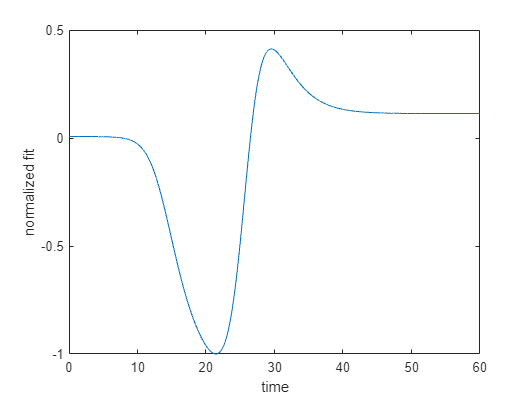


%normalized fit
[MinFit, IdxMin] = min(FitTTime);
NormFit = -(FitTTime - VBaseline) / (MinFit - VBaseline);

% plot noorm fit 
figure( 'Name', 'Normalized Fit' );
h2 = plot( TTime, NormFit );
% Label axes
xlabel( 'time');
ylabel( 'normalized fit');


IndexBelowThreshold = (NormFit >= -ThresholdLevel);
IndexBeforeMin = IndexBelowThreshold(1:IdxMin);
TimeBeforeThreshold = TTime(IndexBeforeMin);
[TimeThrehold, IdxTimeThrehold] = max(TimeBeforeThreshold);
TimeThrehold;

IndexBelowThreshold10 = (NormFit >= -0.1);
IndexBeforeMin10 = IndexBelowThreshold10(1:IdxMin);
TimeBeforeThreshold10 = TTime(IndexBeforeMin10);
[TimeThrehold10, IdxTimeThrehold10] = max(TimeBeforeThreshold10);
TimeThrehold10

TimeThrehold10 = 11.6900


IndexBelowThreshold15 = (NormFit >= -0.15);
IndexBeforeMin15 = IndexBelowThreshold15(1:IdxMin);
TimeBeforeThreshold15 = TTime(IndexBeforeMin15);
[TimeThrehold15, IdxTimeThrehold15] = max(TimeBeforeThreshold15);
TimeThrehold15

TimeThrehold15 = 12.3500


IndexBelowThreshold20 = (NormFit >= -0.2);
IndexBeforeMin20 = IndexBelowThreshold20(1:IdxMin);
TimeBeforeThreshold20 = TTime(IndexBeforeMin20);
[TimeThrehold20, IdxTimeThrehold20] = max(TimeBeforeThreshold20);
TimeThrehold20

TimeThrehold20 = 12.8800


TimeThrehold101520 = [TimeThrehold10 ; TimeThrehold15 ; TimeThrehold20];

function y = FitVelocityFunction(fitcoeffvals, x)
y = fitcoeffvals(4)./ (1 + exp((x-fitcoeffvals(8))/fitcoeffvals(1)))...
    + fitcoeffvals(5)./ (1 + exp(-(x-fitcoeffvals(9))/fitcoeffvals(2)))...
    + fitcoeffvals(6)./ (1 + exp(-(x-fitcoeffvals(10))/fitcoeffvals(3))).^2 ...
    + fitcoeffvals(7);
end